## Pain > (Vicarious & Cognitive)

#### Pain > VC :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0009.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0009.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 141.581190 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6191567  Bit rate: 22.56 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              03:06:36 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain > VC :: Plot diagnostics, before l2norm

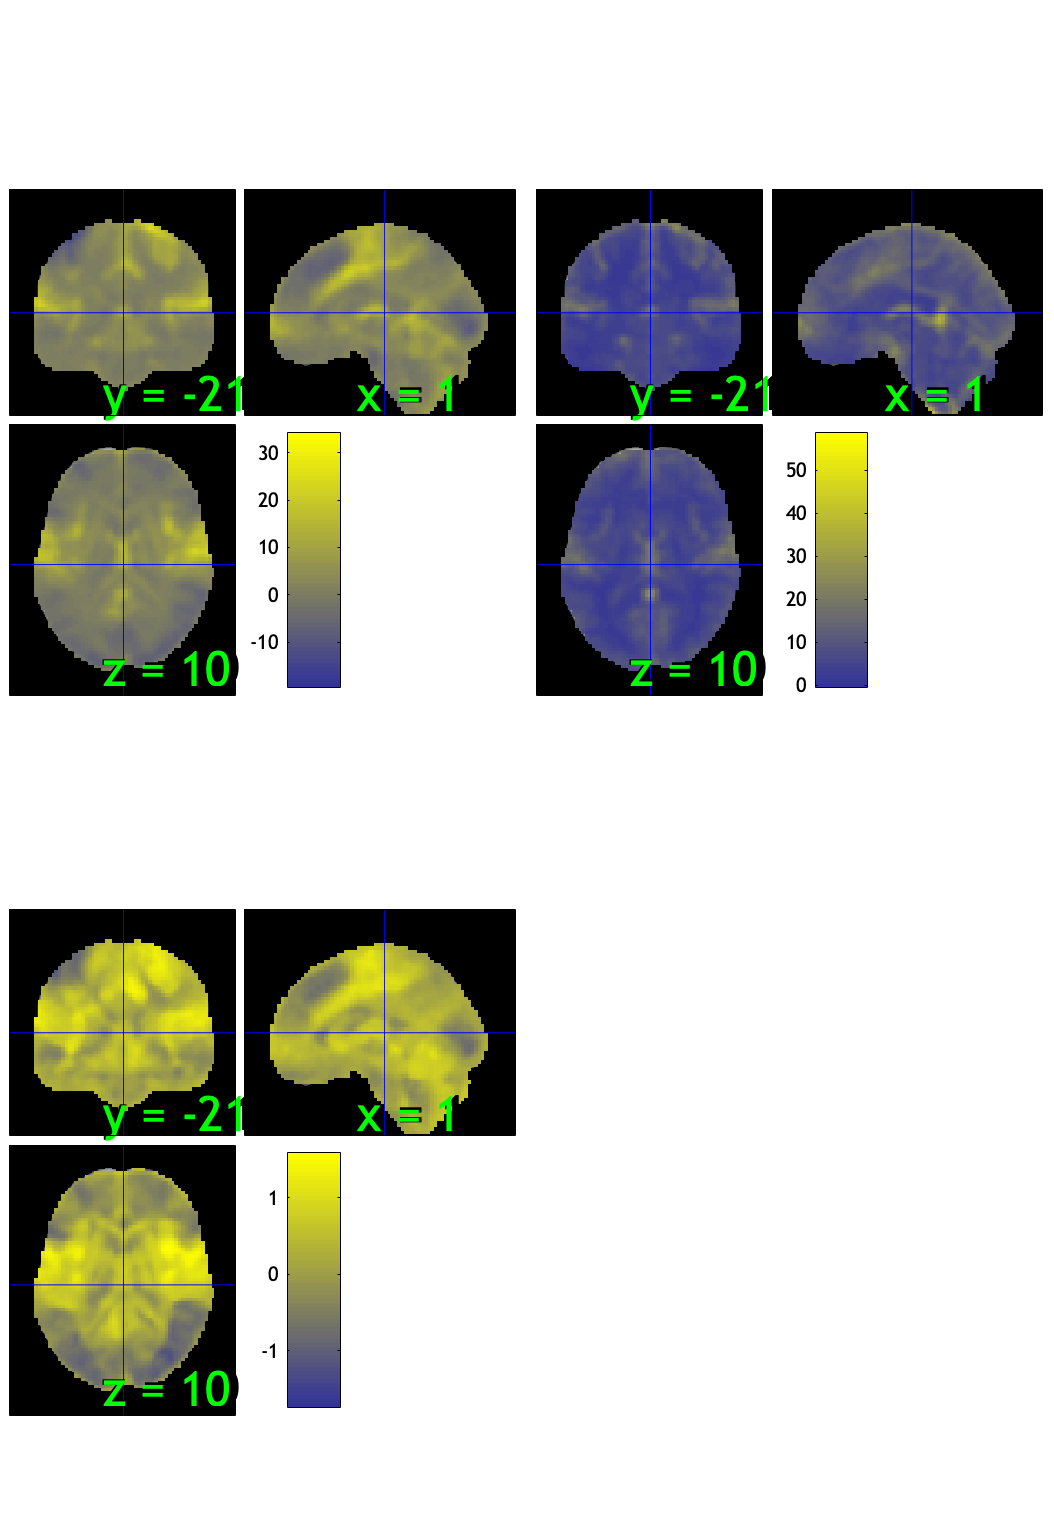

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.75%
Expected 3.20 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 24 33 35 
Uncorrected: 5 images		Cases 2 24 33 34 35 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 17 20 33 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                              

SPM12: spm_check_registration (v7759)              03:07:14 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

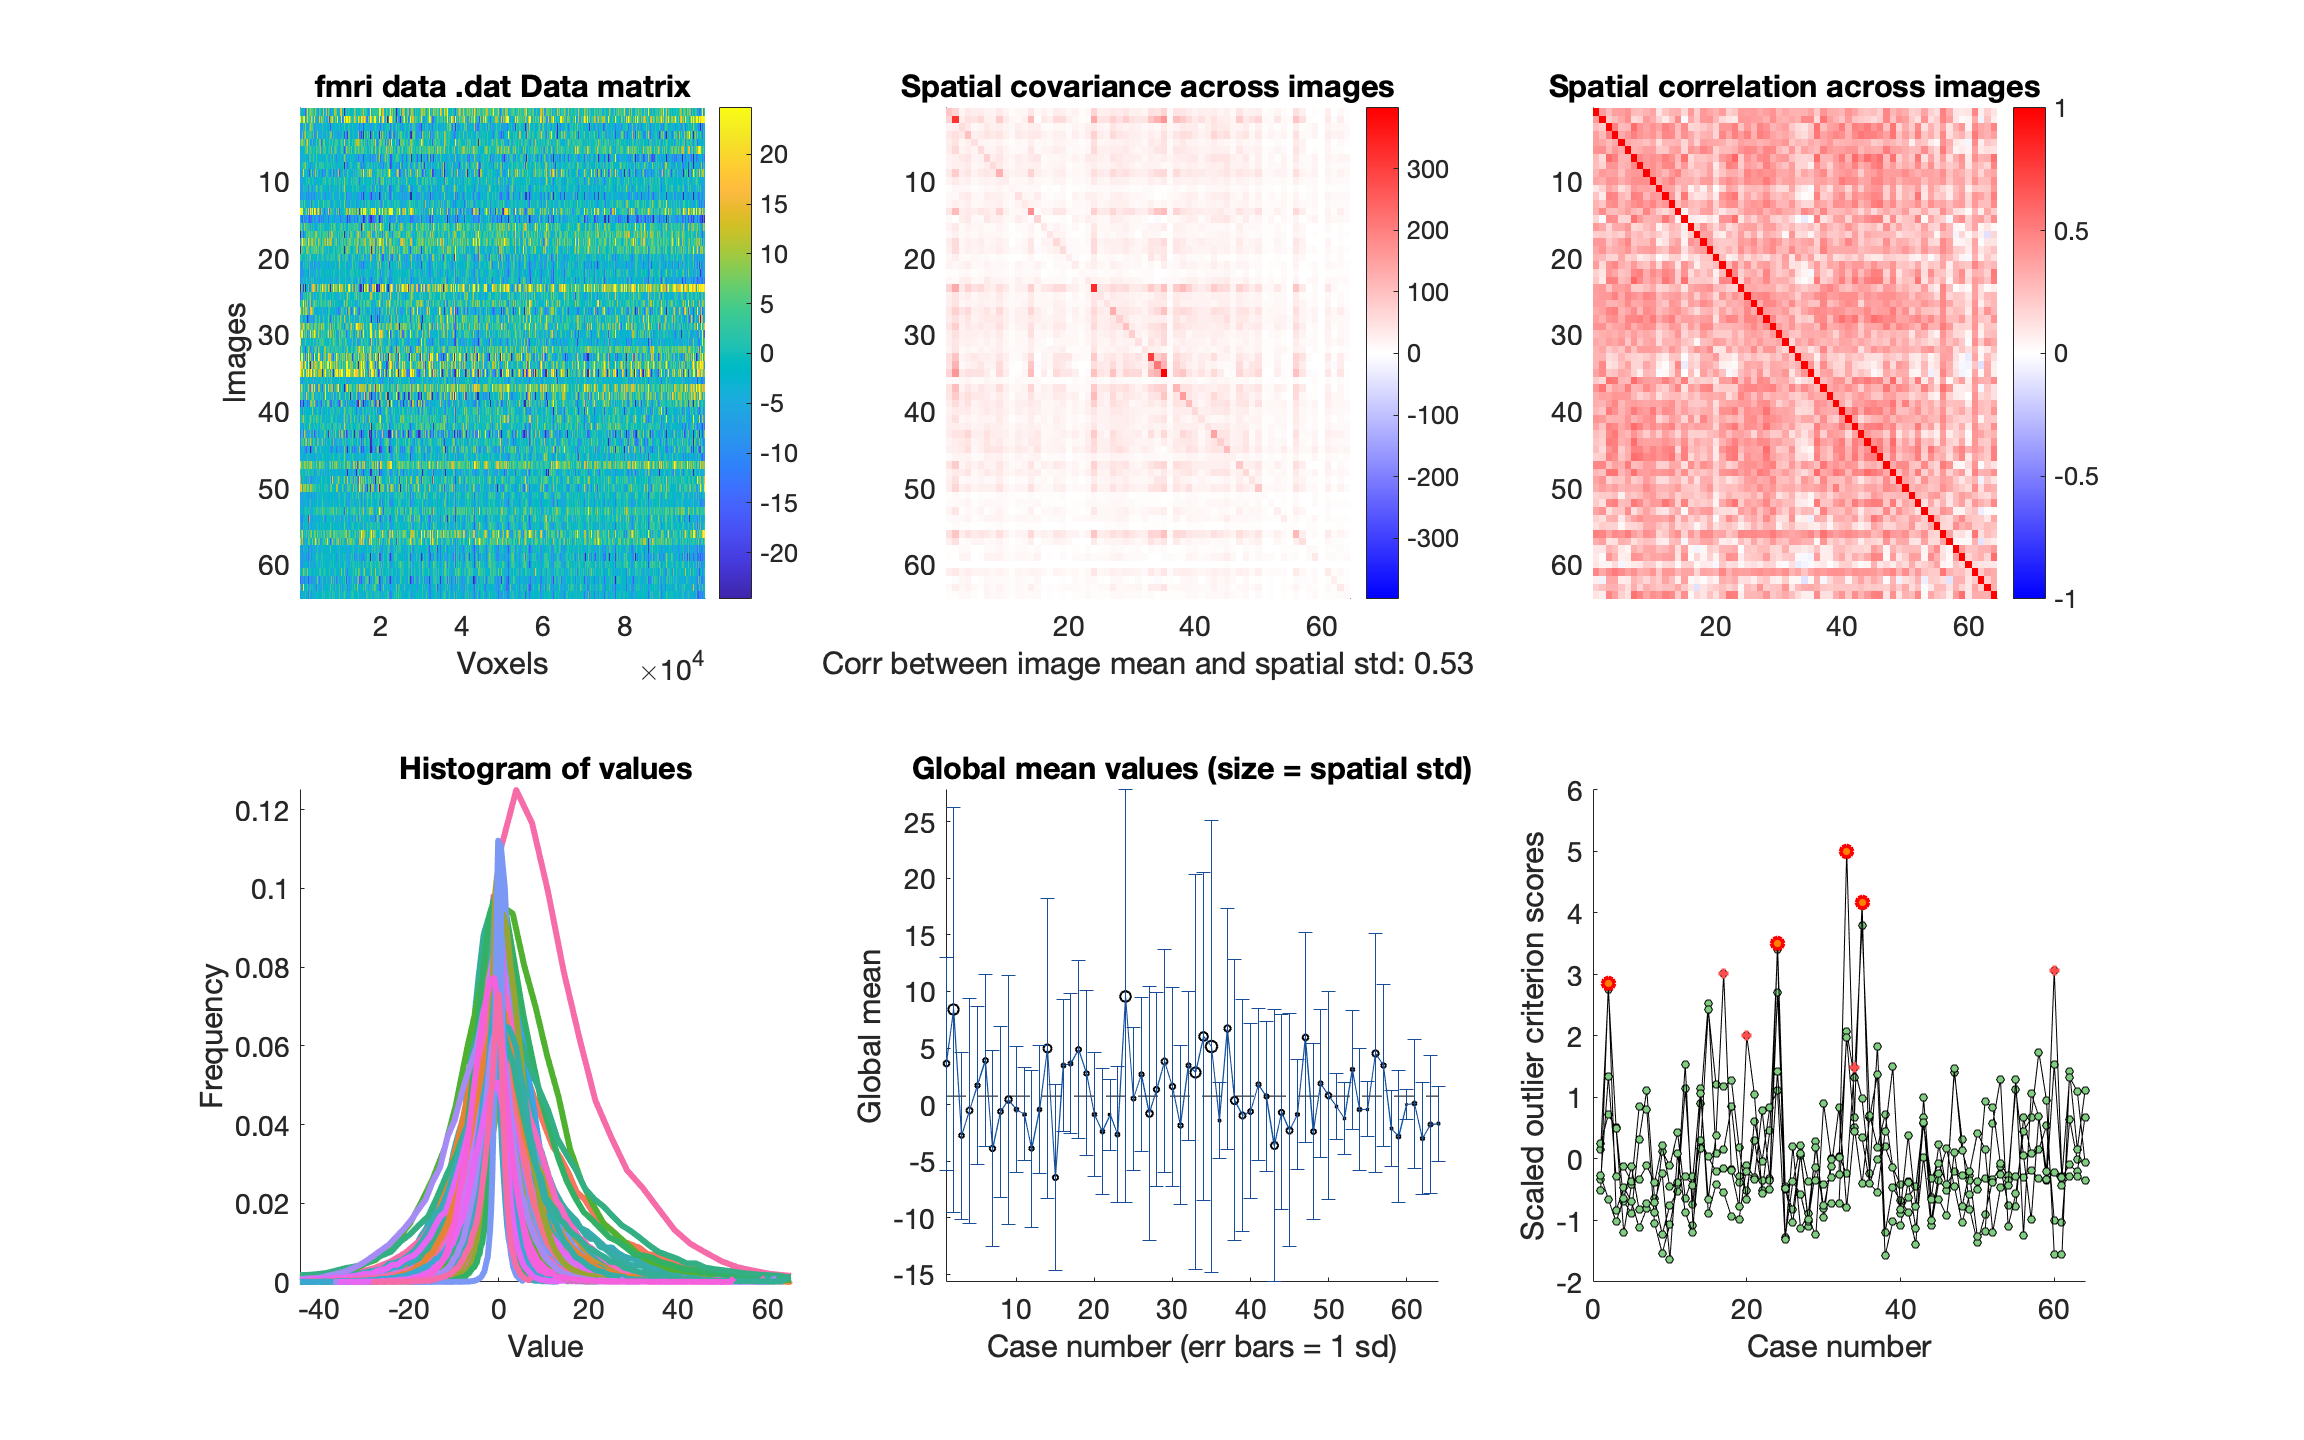

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain > VC :: run robfit

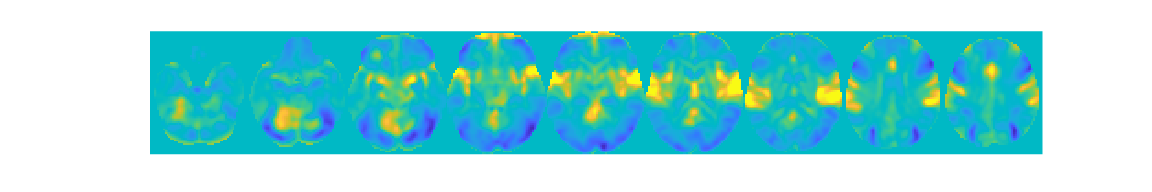

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 64


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×60 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [60×12 char]
              fullpath: [64×109 char]
           files_exist: [64×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×60 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [60×12 char]
              fullpath: [60×109 char]
           files_exist: [64×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×60 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [60×12 char]
              fullpath: [60×109 char]
           files_exist: [60×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 4 participants, size is now 60


#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


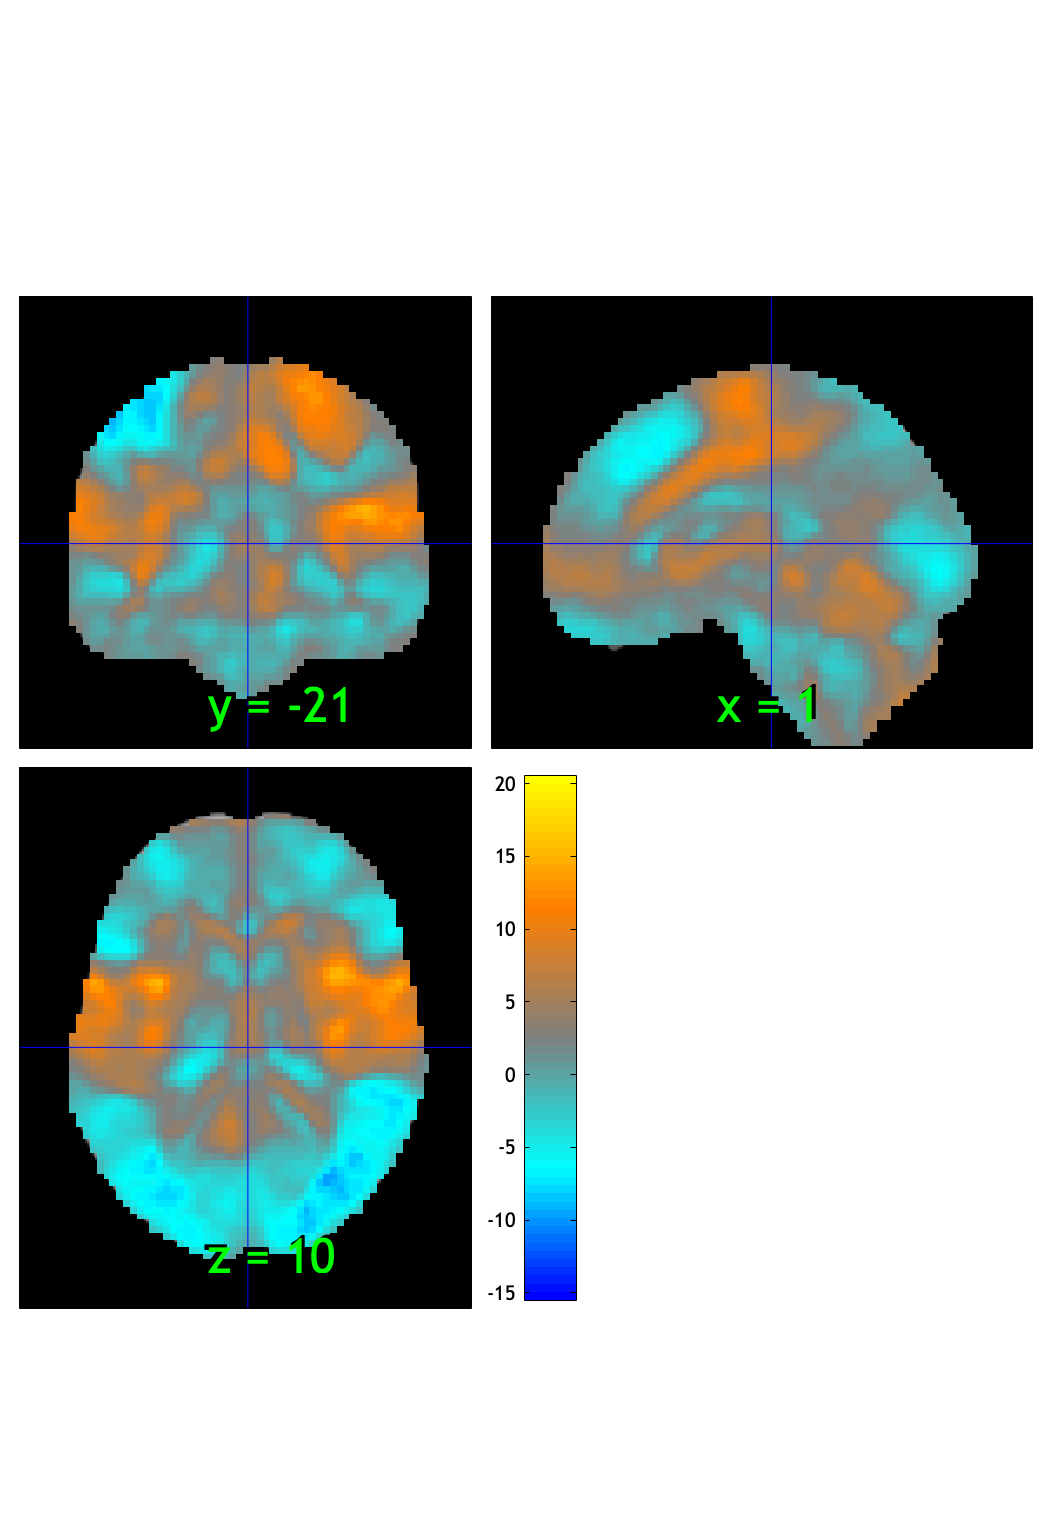

SPM12: spm_check_registration (v7759)              03:07:20 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.029630

Image   1
 32 contig. clusters, sizes   1 to 58721
Positive effect: 28826 voxels, min p-value: 0.00000000
Negative effect: 30338 voxels, min p-value: 0.00000000


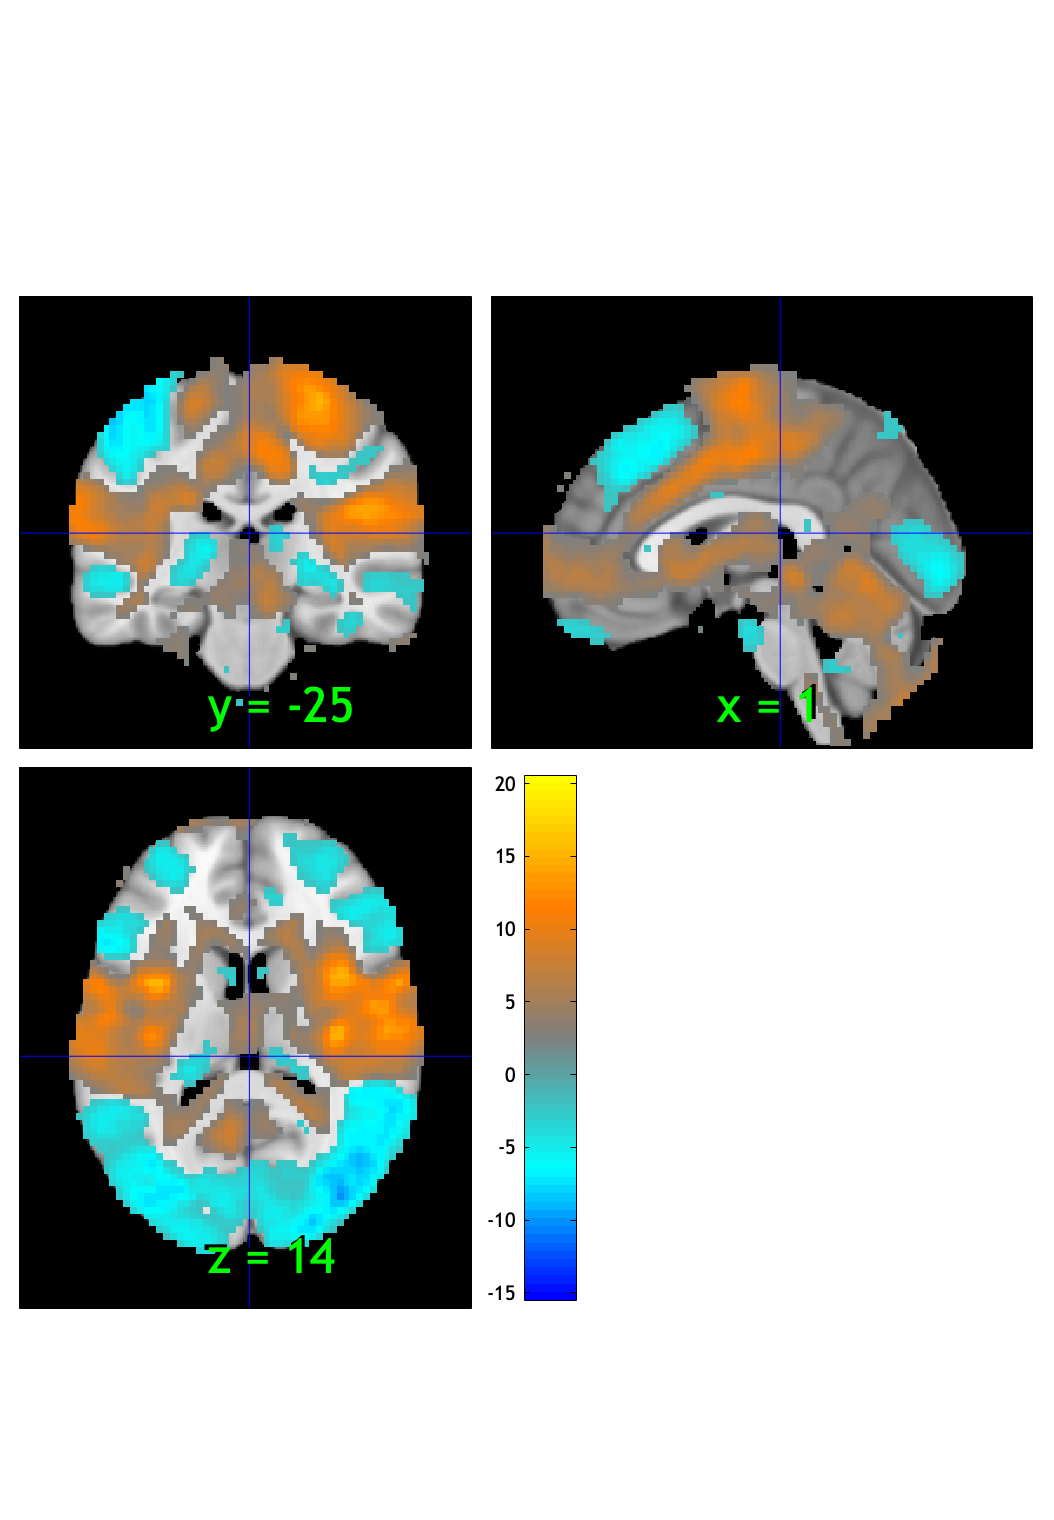

SPM12: spm_check_registration (v7759)              03:07:21 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×32 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1390 voxels displayed, 57774 not displayed on these slices


sagittal montage: 1292 voxels displayed, 57872 not displayed on these slices


sagittal montage: 1293 voxels displayed, 57871 not displayed on these slices


axial montage: 10730 voxels displayed, 48434 not displayed on these slices


axial montage: 11645 voxels displayed, 47519 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


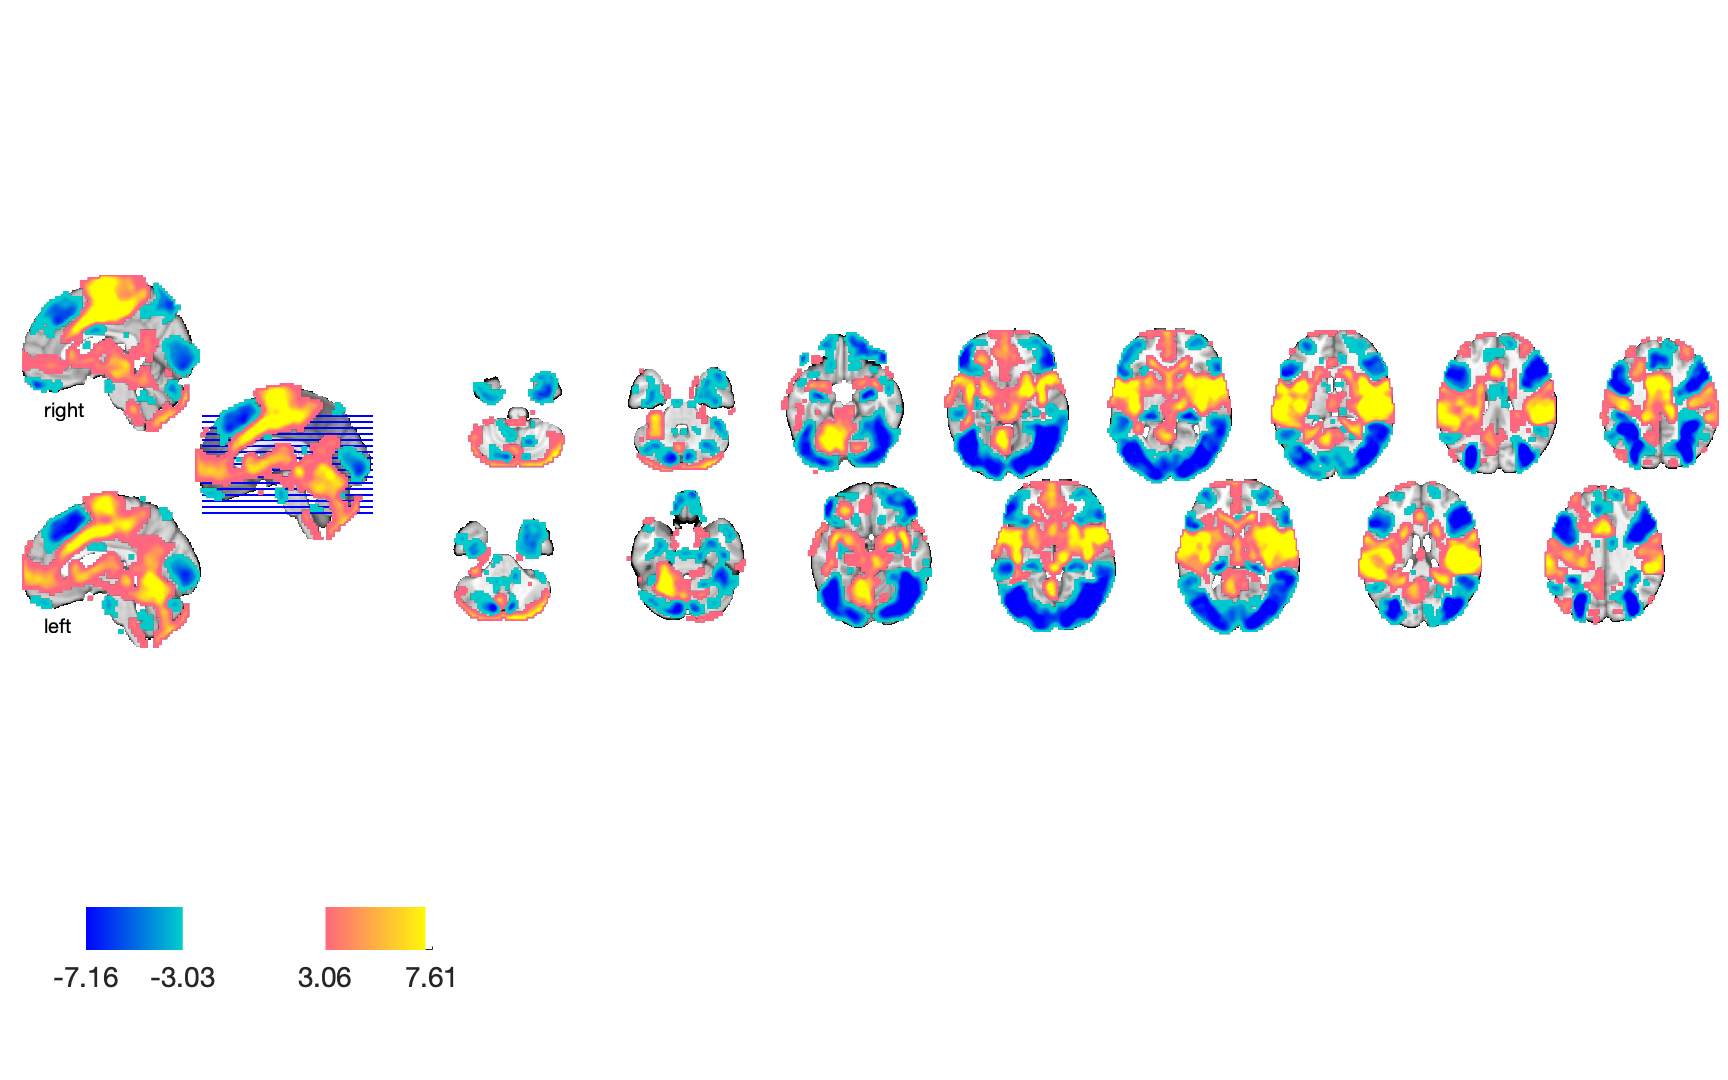

drawnow, snapnow;

## Vicarious > (Pain & Cognitive)

clear all

#### Vicarious > PC :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0010.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0010.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 225.752226 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6187555  Bit rate: 22.56 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Vicarious > PC :: `check data coverage`

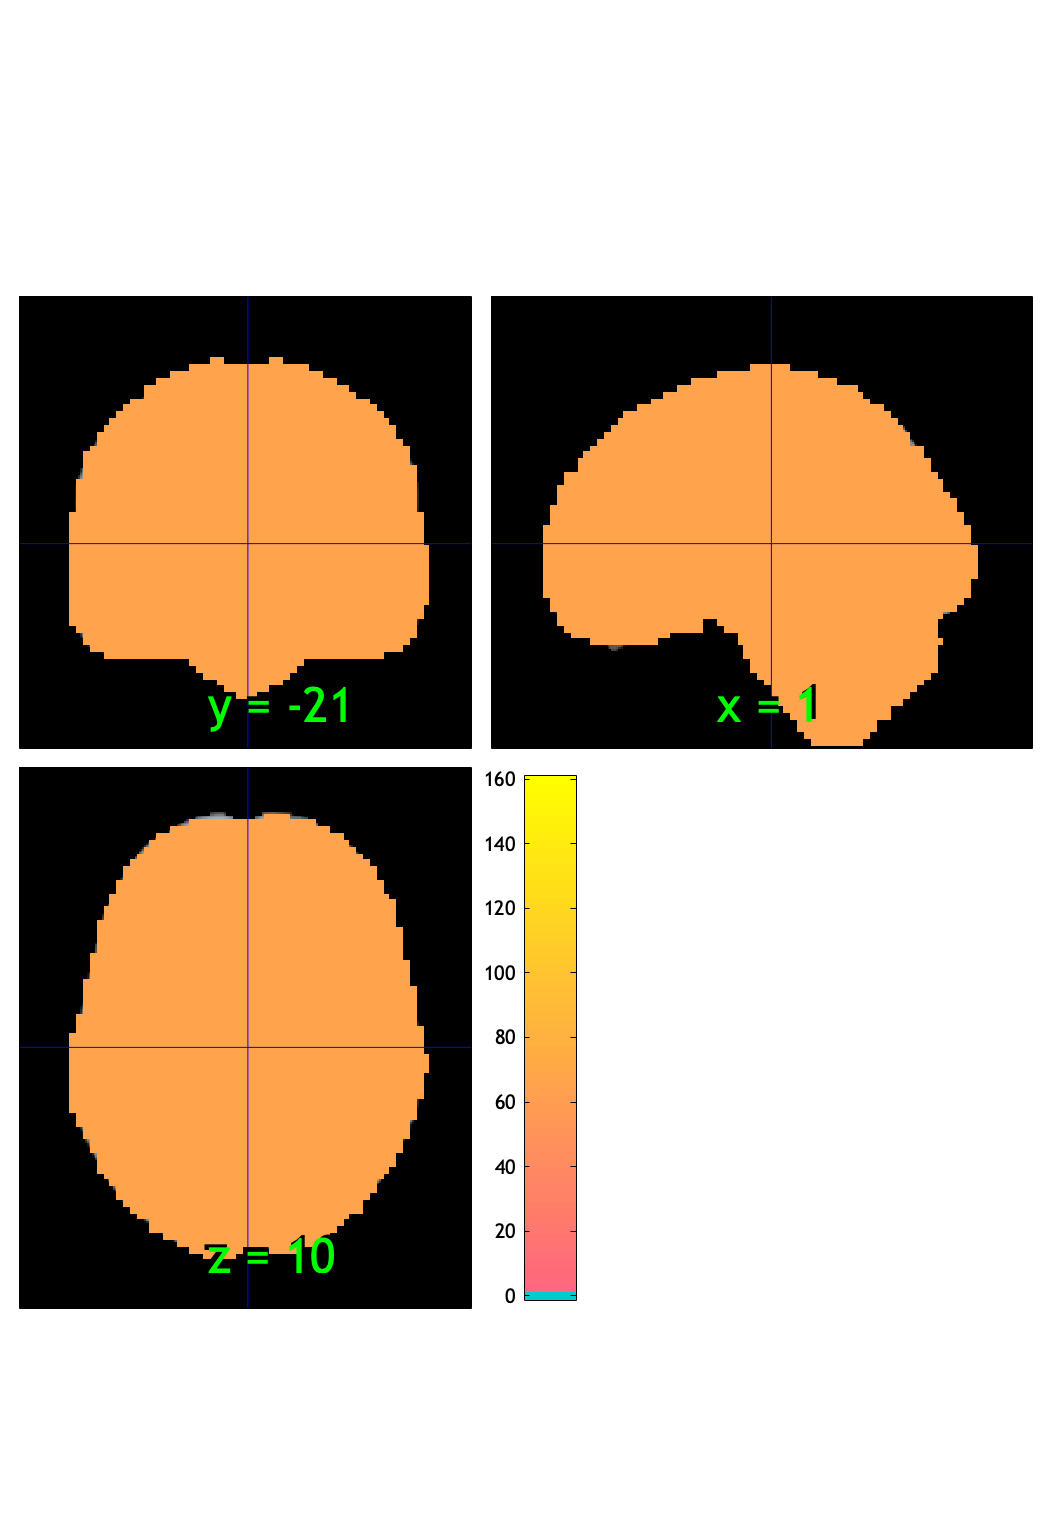

SPM12: spm_check_registration (v7759)              03:11:56 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious > PC :: Plot diagnostics, before l2norm

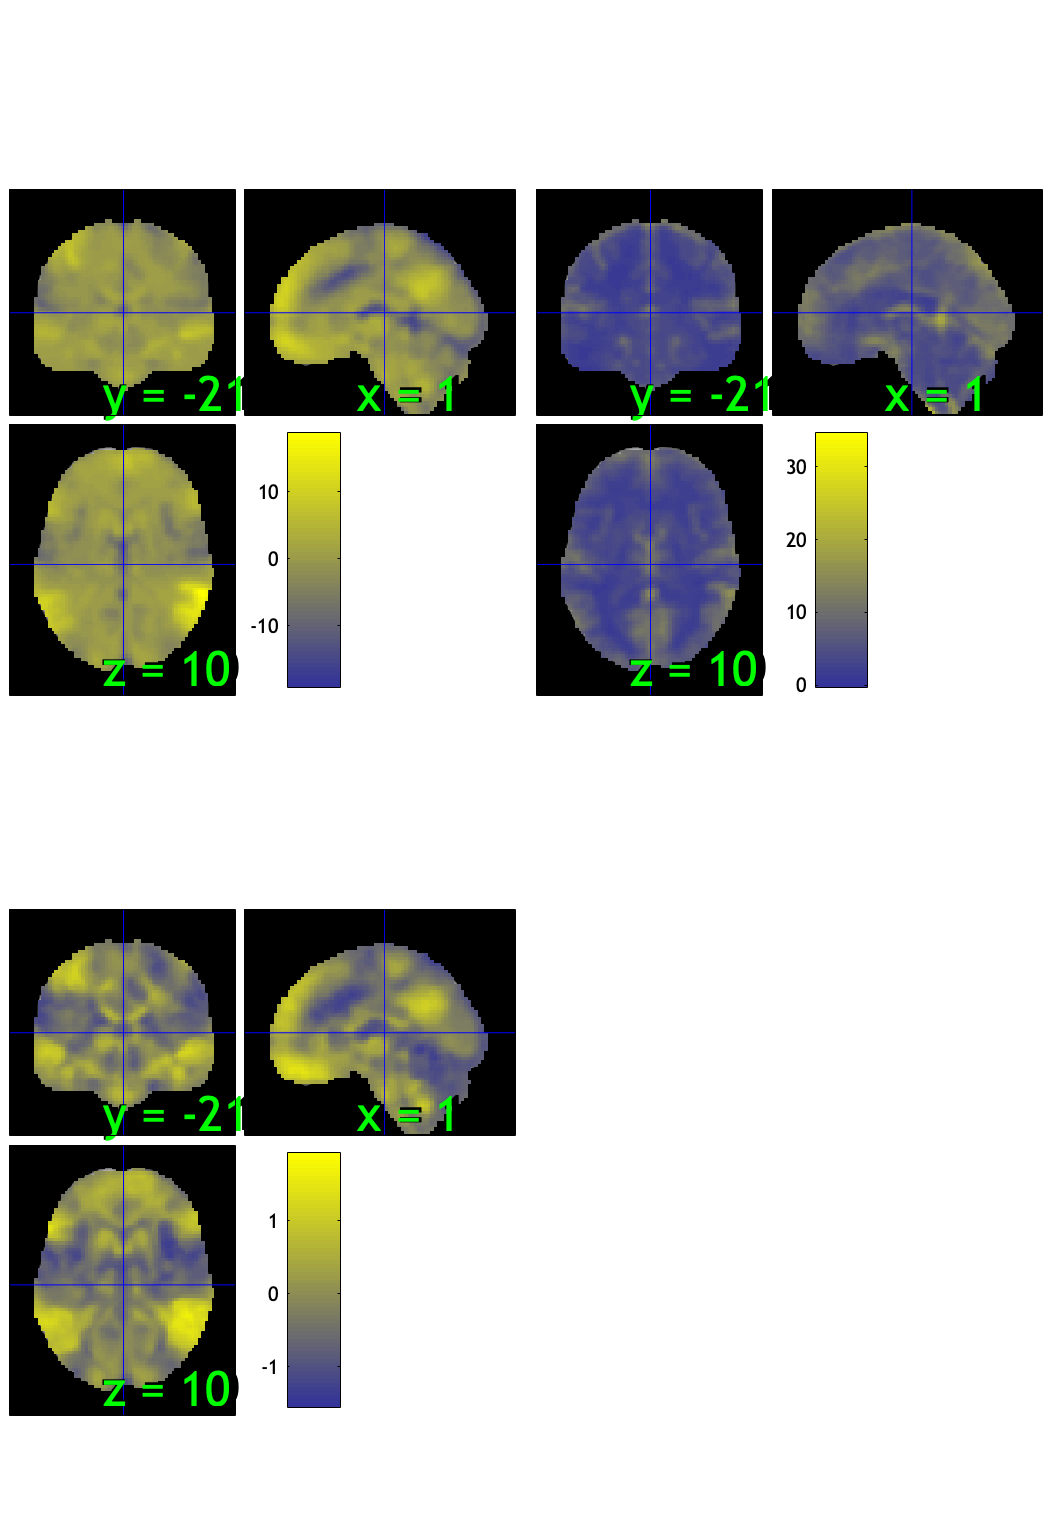

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.31%
Expected 3.20 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 2 24 33 35 38 
Uncorrected: 6 images		Cases 2 24 33 35 38 43 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 11 
Uncorrected: 2 images		Cases 11 62 

Mahalanobis (cov and corr, q<0.05 corrected):
  6 images 
                               Outlier_count    Percentage
                         

SPM12: spm_check_registration (v7759)              03:12:37 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

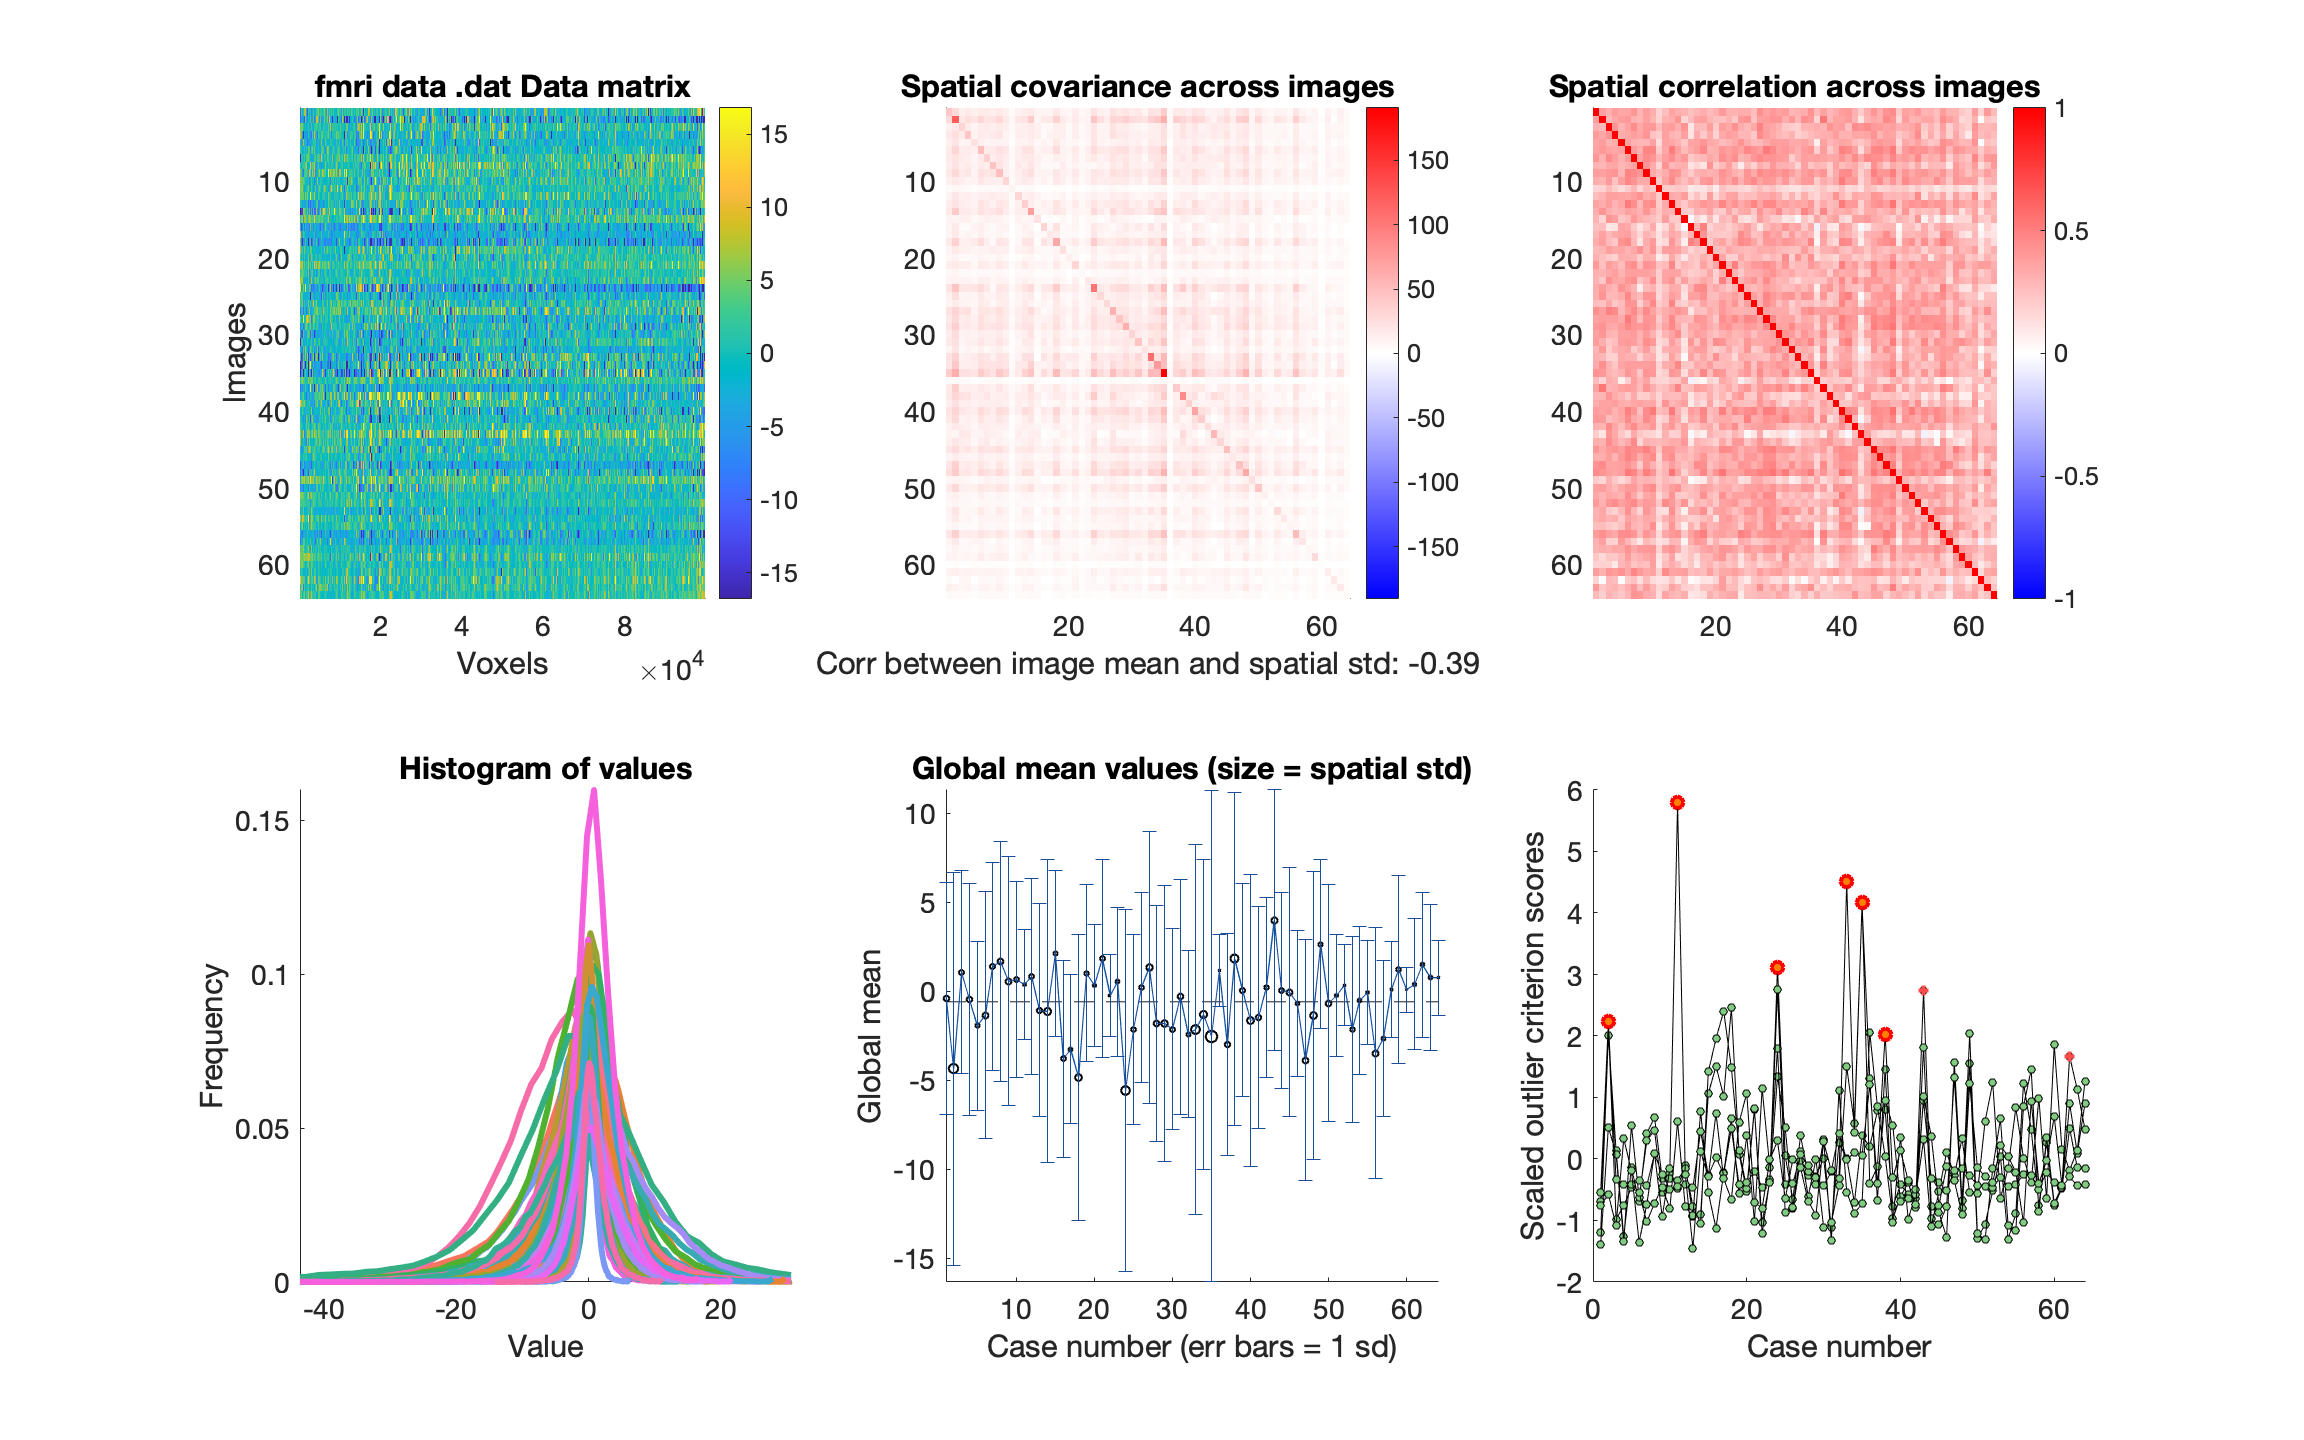

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


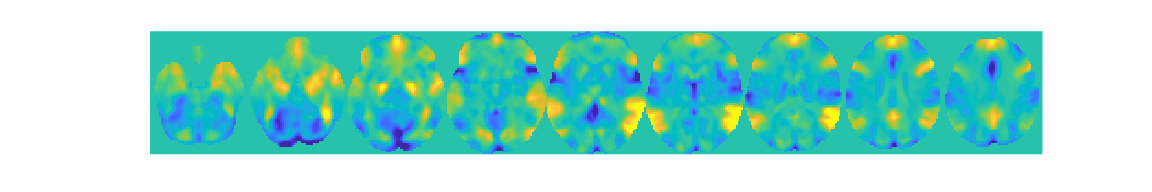

wh_outlier_uncorr = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious > PC :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 64


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [64×109 char]
           files_exist: [64×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [58×109 char]
           files_exist: [64×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [58×109 char]
           files_exist: [58×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 6 participants, size is now 58


#### Vicarious > PC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


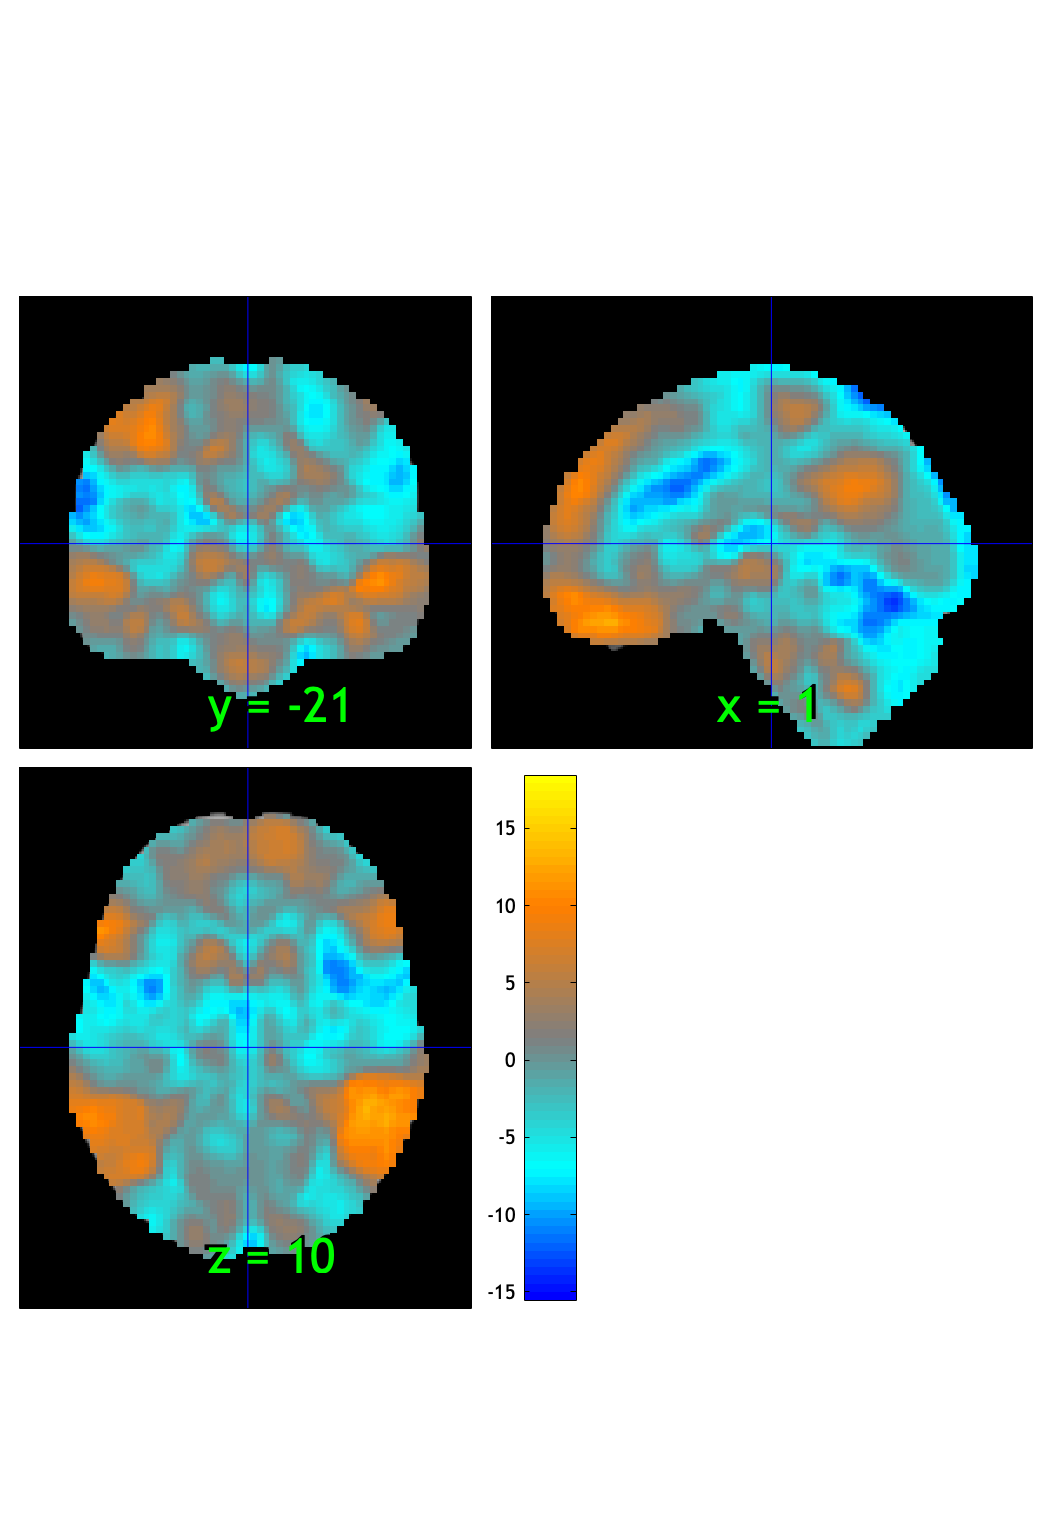

SPM12: spm_check_registration (v7759)              03:12:42 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.031548

Image   1
 17 contig. clusters, sizes   1 to 62394
Positive effect: 27674 voxels, min p-value: 0.00000000
Negative effect: 35332 voxels, min p-value: 0.00000000


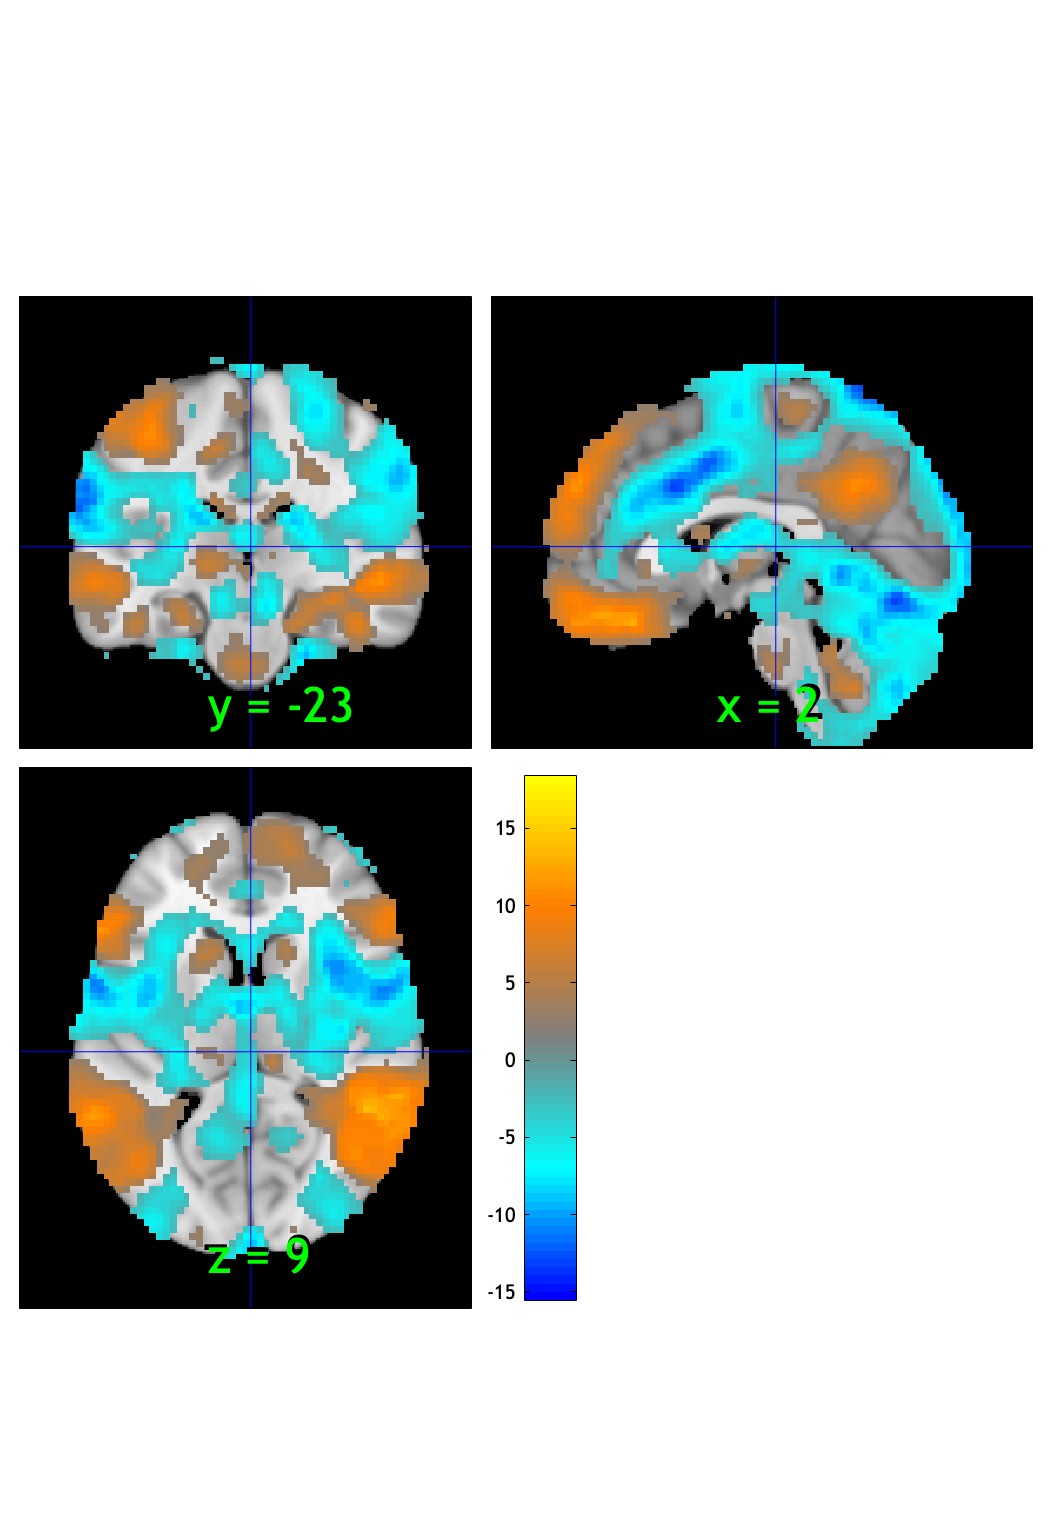

SPM12: spm_check_registration (v7759)              03:12:44 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×17 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1568 voxels displayed, 61438 not displayed on these slices


sagittal montage: 1631 voxels displayed, 61375 not displayed on these slices


sagittal montage: 1629 voxels displayed, 61377 not displayed on these slices


axial montage: 11574 voxels displayed, 51432 not displayed on these slices


axial montage: 12560 voxels displayed, 50446 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


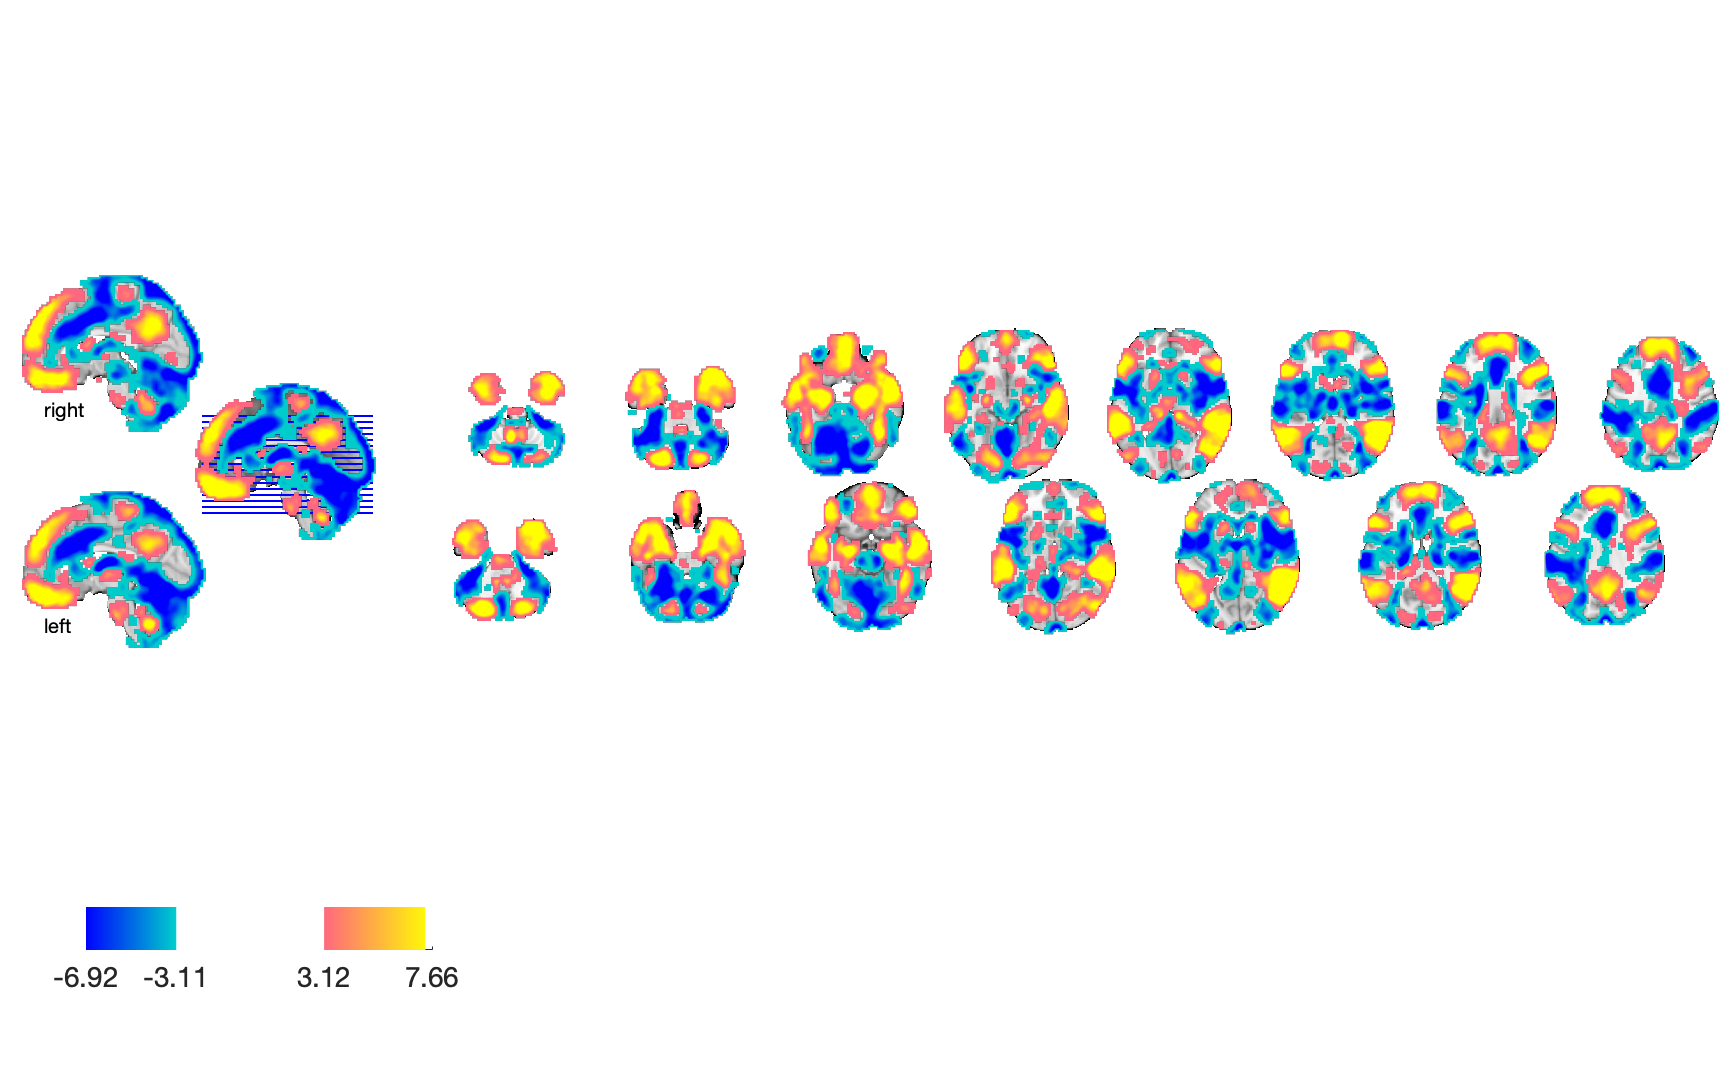

drawnow, snapnow;

## Cognitive > (Pain & Vicarious)

#### Cognitive > PV :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0011.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0011.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 213.231908 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6188943  Bit rate: 22.56 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Cognitive > PV :: `check data coverage`

SPM12: spm_check_registration (v7759)              03:17:09 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Cognitive > PV :: Plot diagnostics, before l2norm

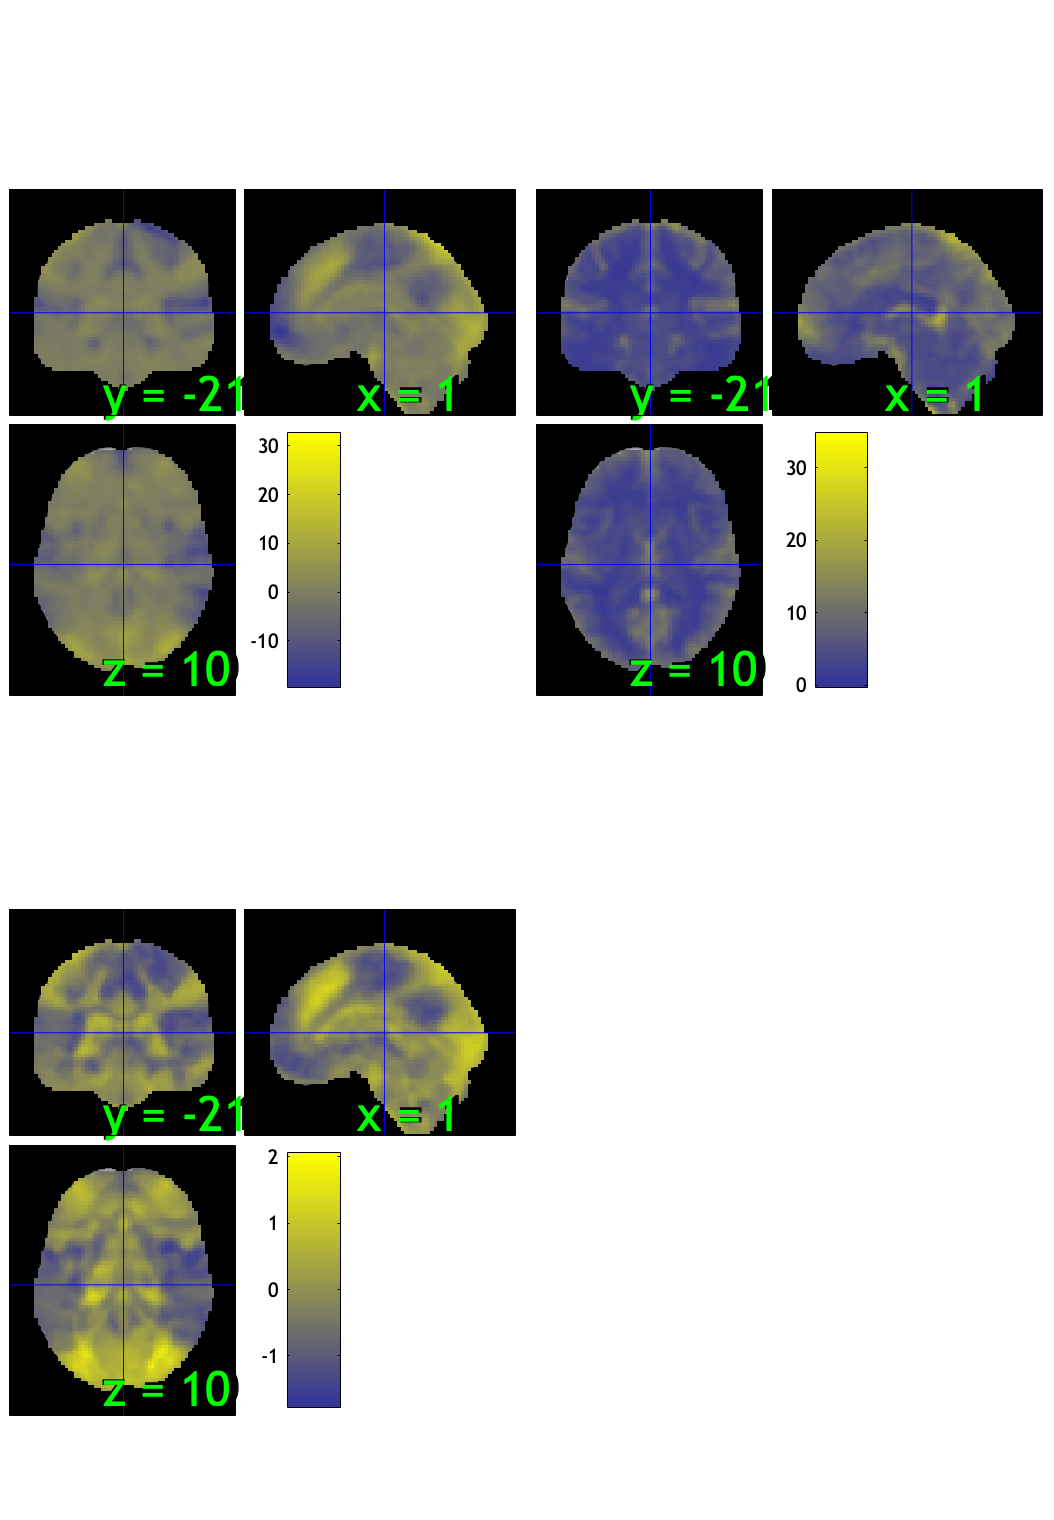

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 31.25%
Expected 3.20 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 24 35 
Uncorrected: 4 images		Cases 24 33 35 45 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 46.88%
Expected 3.20 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 20 57 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              03:17:39 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

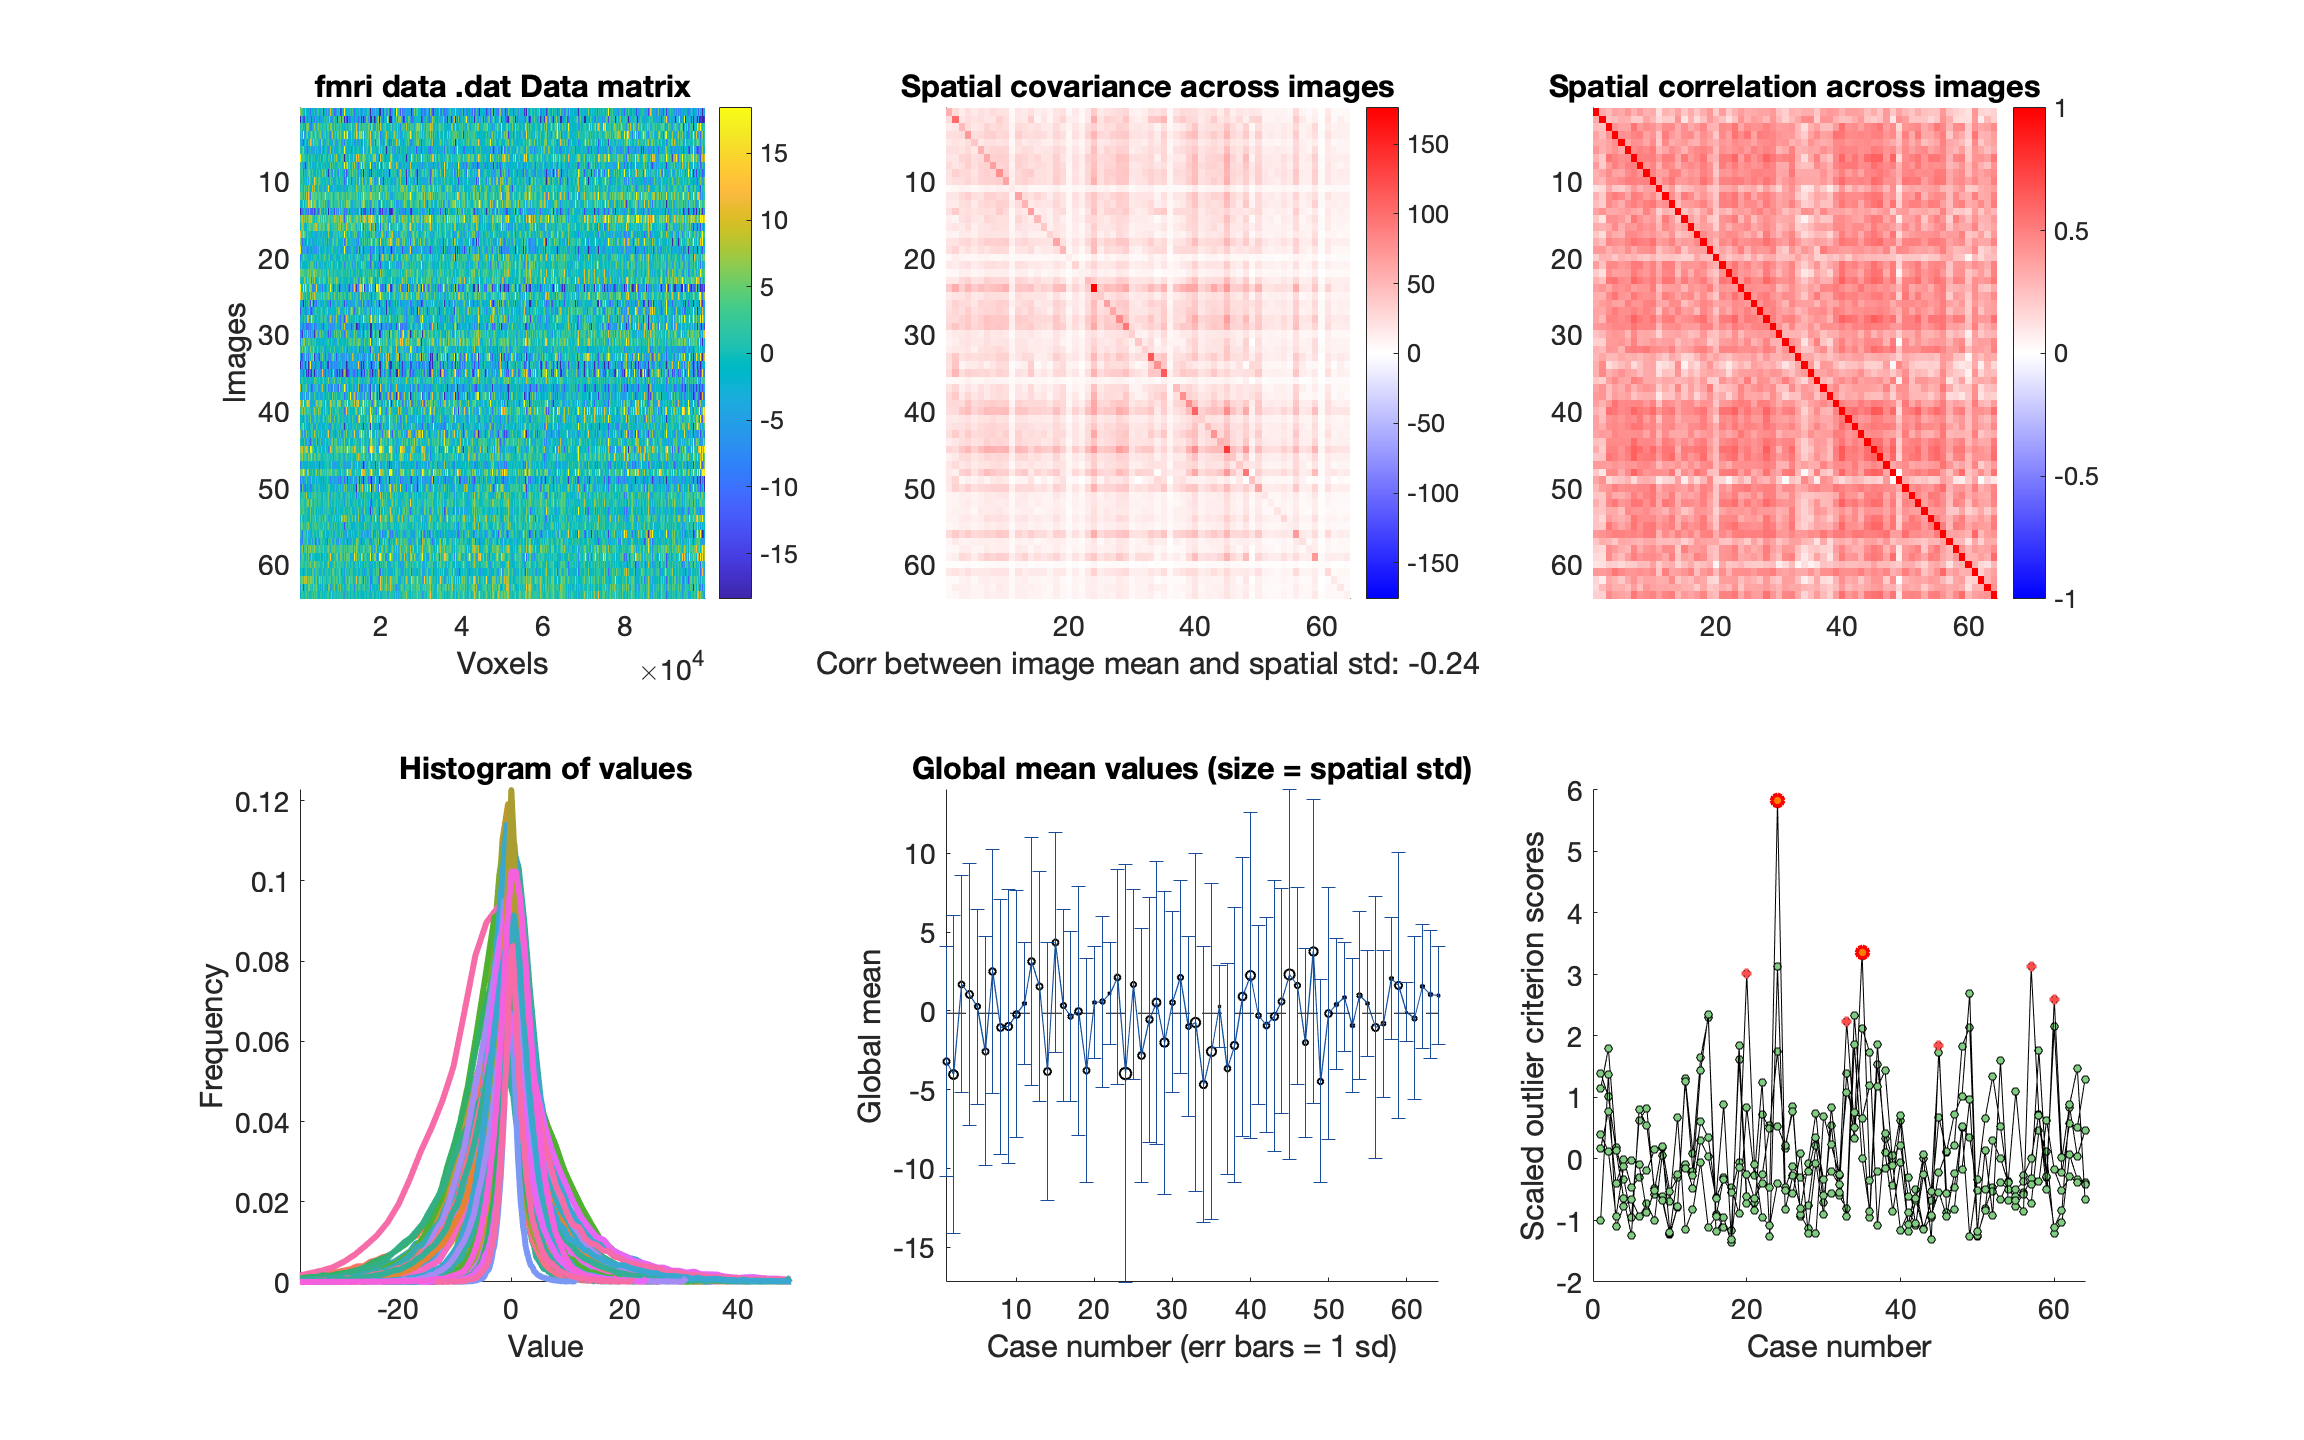

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


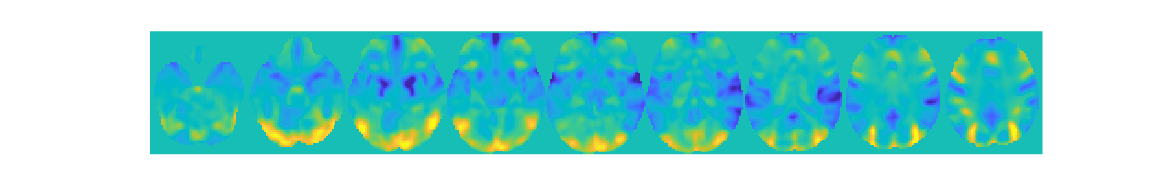

wh_outlier_uncorr = 64×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 64×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive > PV :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 64


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×62 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [62×12 char]
              fullpath: [64×109 char]
           files_exist: [64×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×62 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [62×12 char]
              fullpath: [62×109 char]
           files_exist: [64×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×62 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [62×12 char]
              fullpath: [62×109 char]
           files_exist: [62×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 2 participants, size is now 62


#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


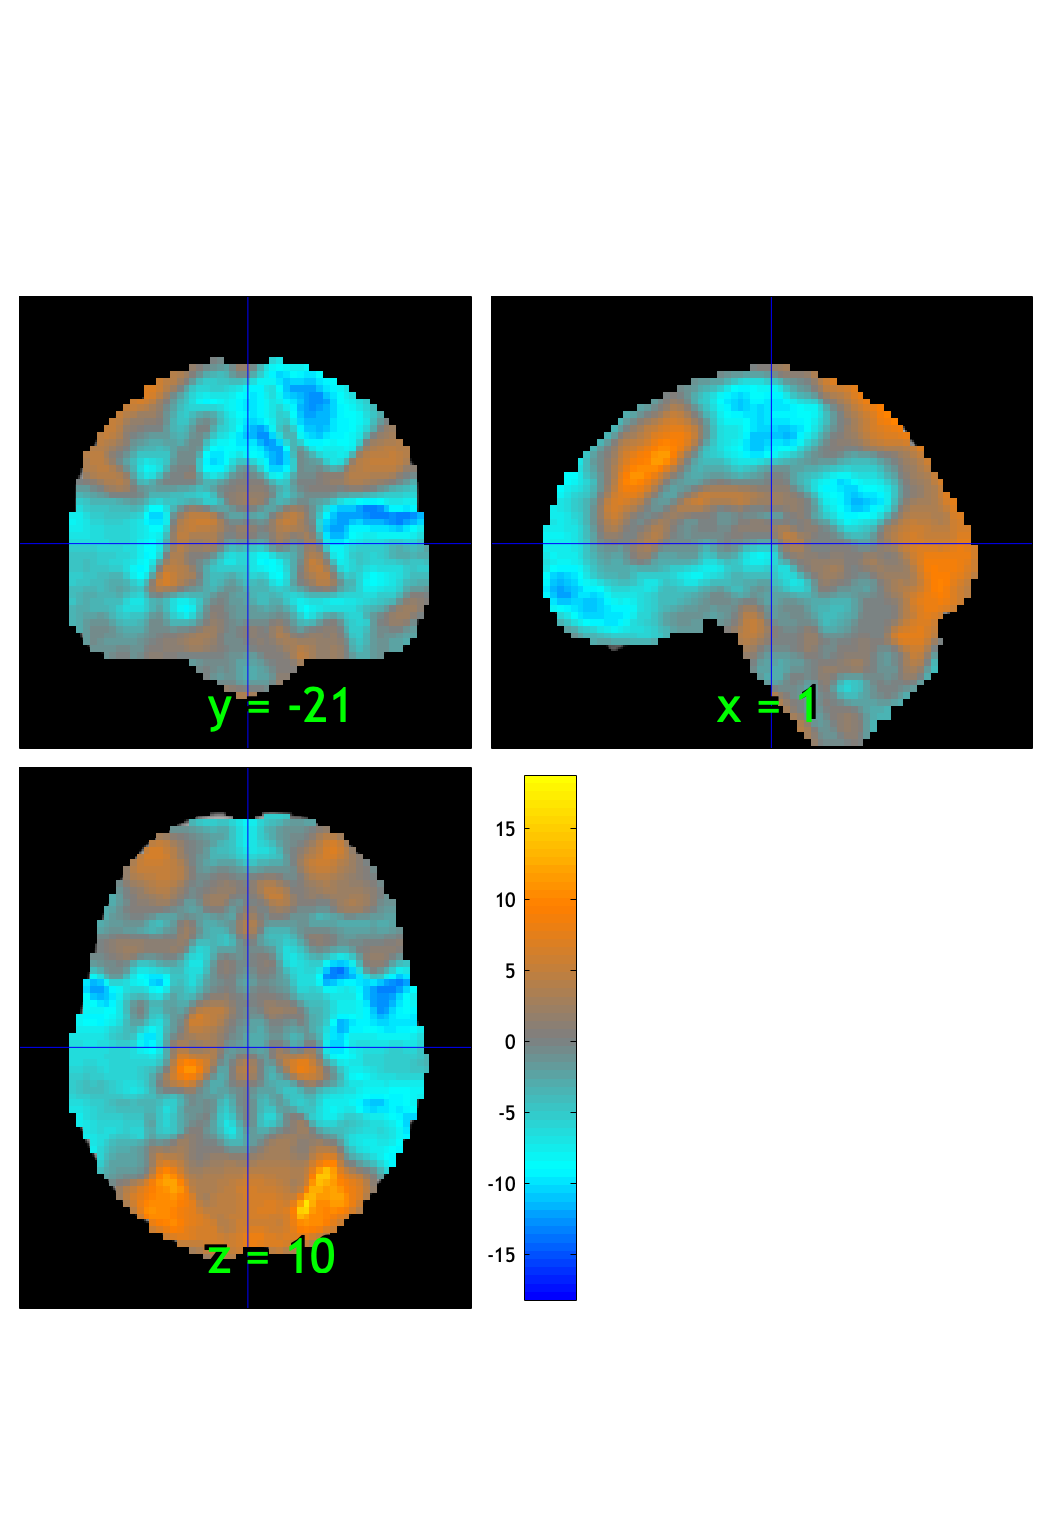

SPM12: spm_check_registration (v7759)              03:17:45 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.033736

Image   1
 18 contig. clusters, sizes   1 to 67101
Positive effect: 29351 voxels, min p-value: 0.00000000
Negative effect: 38013 voxels, min p-value: 0.00000000


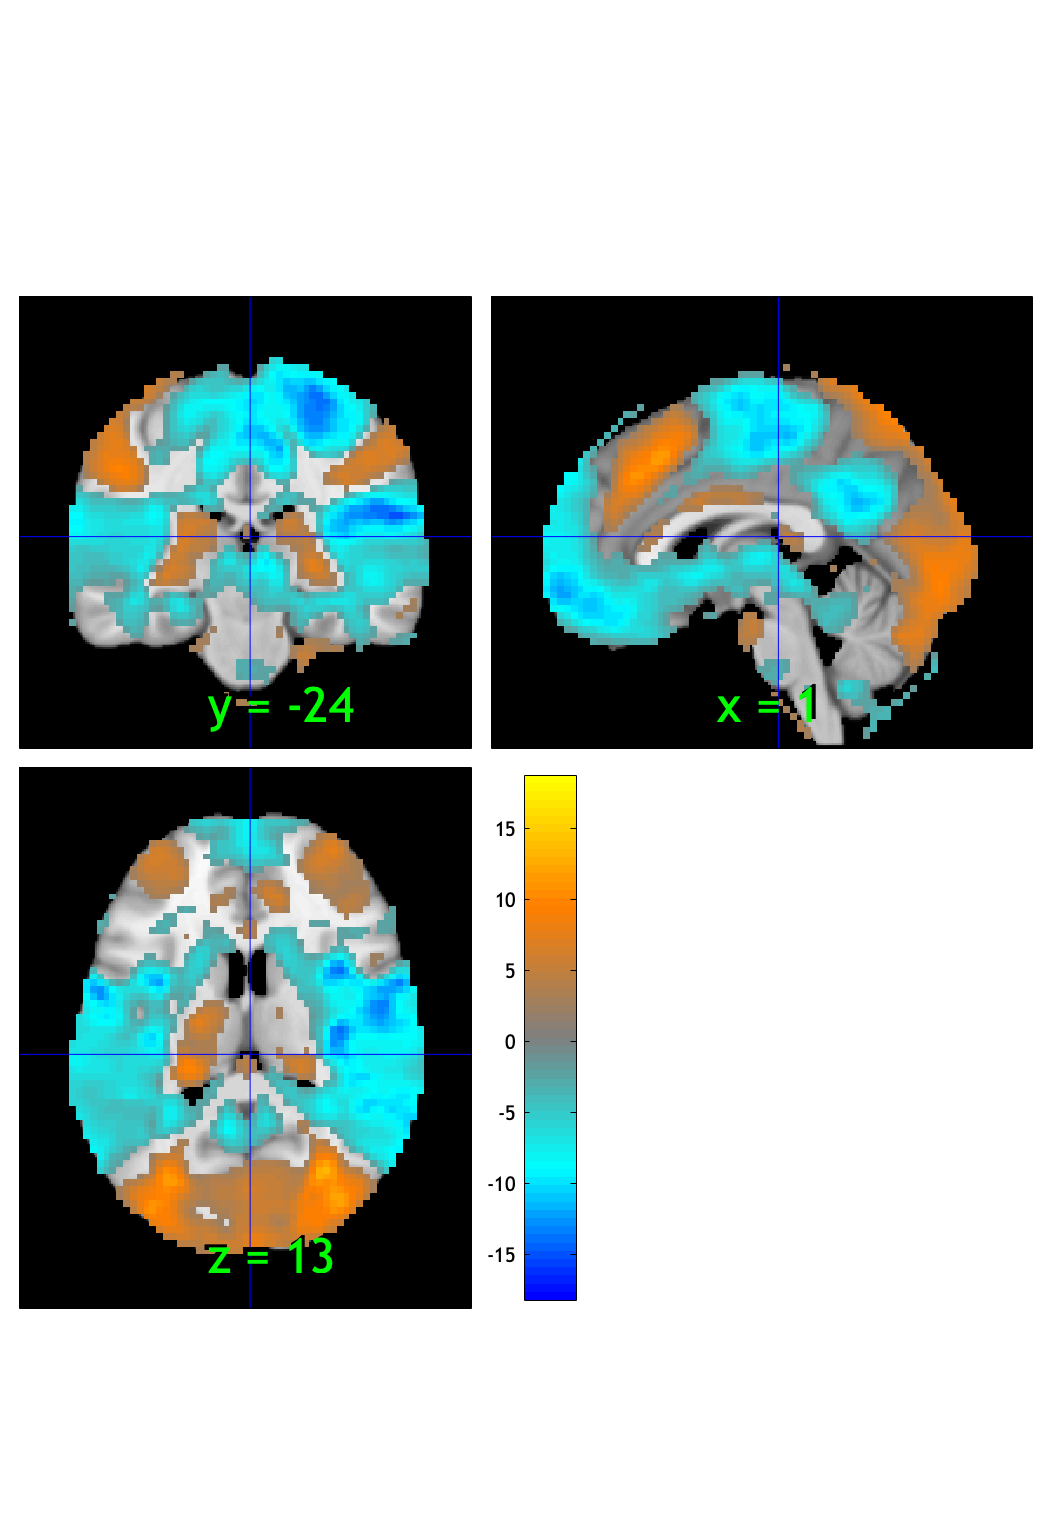

SPM12: spm_check_registration (v7759)              03:17:46 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


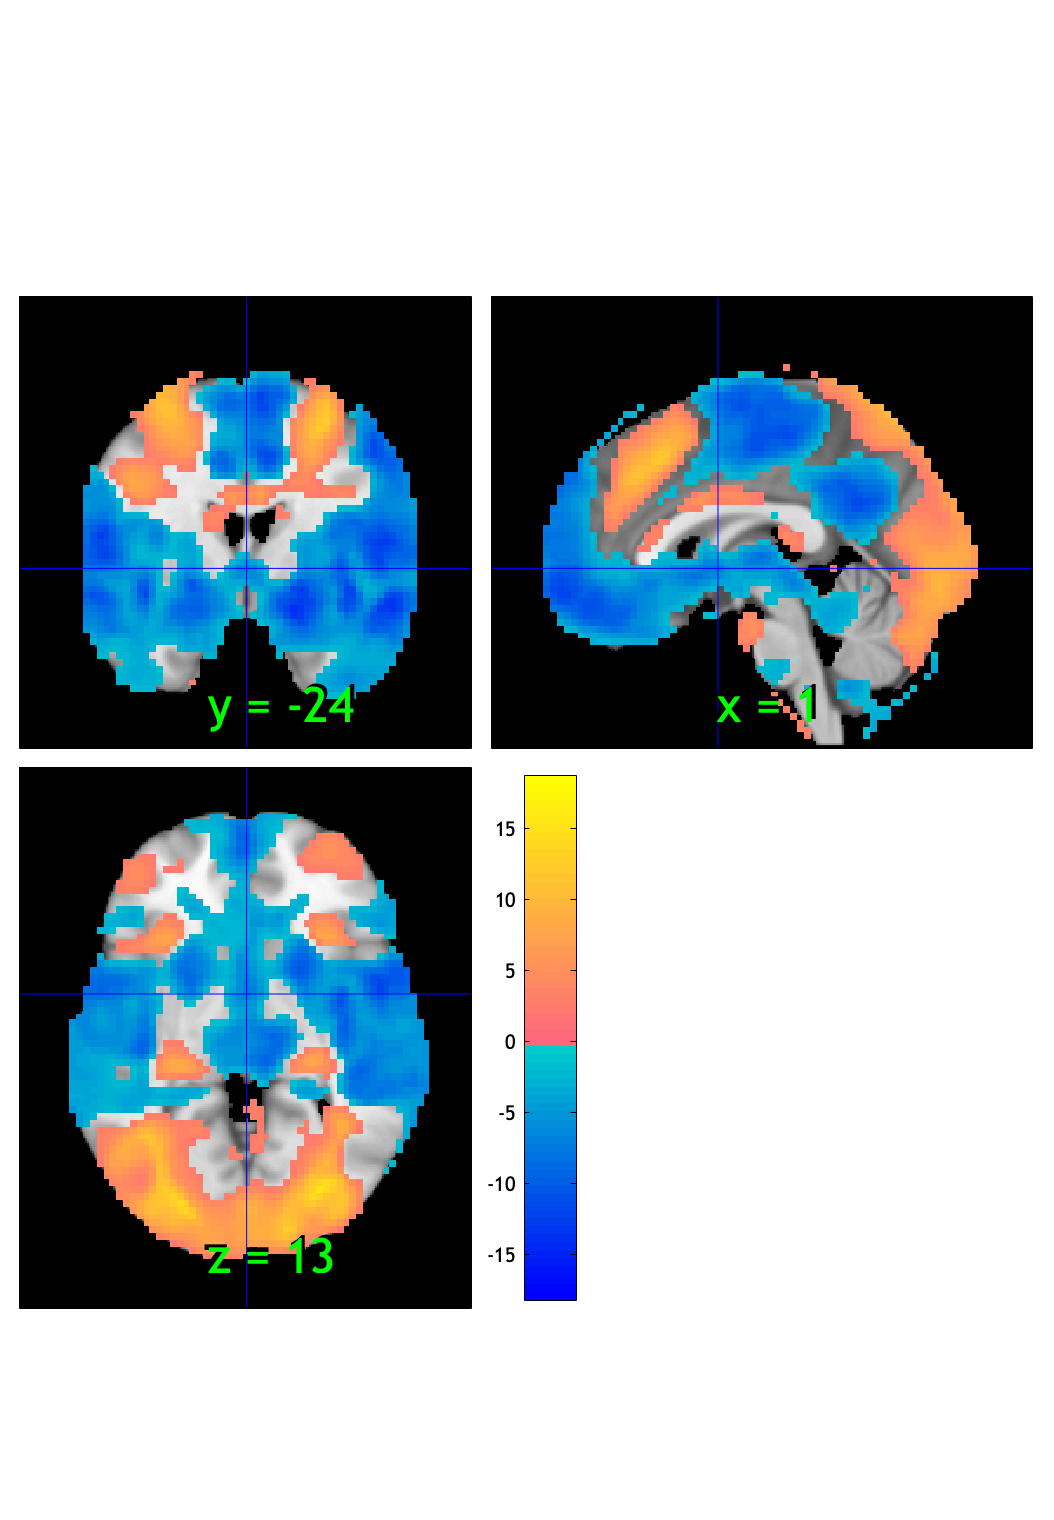

ans = 1×1 cell array
    {1×18 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1573 voxels displayed, 65791 not displayed on these slices


sagittal montage: 1632 voxels displayed, 65732 not displayed on these slices


sagittal montage: 1499 voxels displayed, 65865 not displayed on these slices


axial montage: 12505 voxels displayed, 54859 not displayed on these slices


axial montage: 13658 voxels displayed, 53706 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


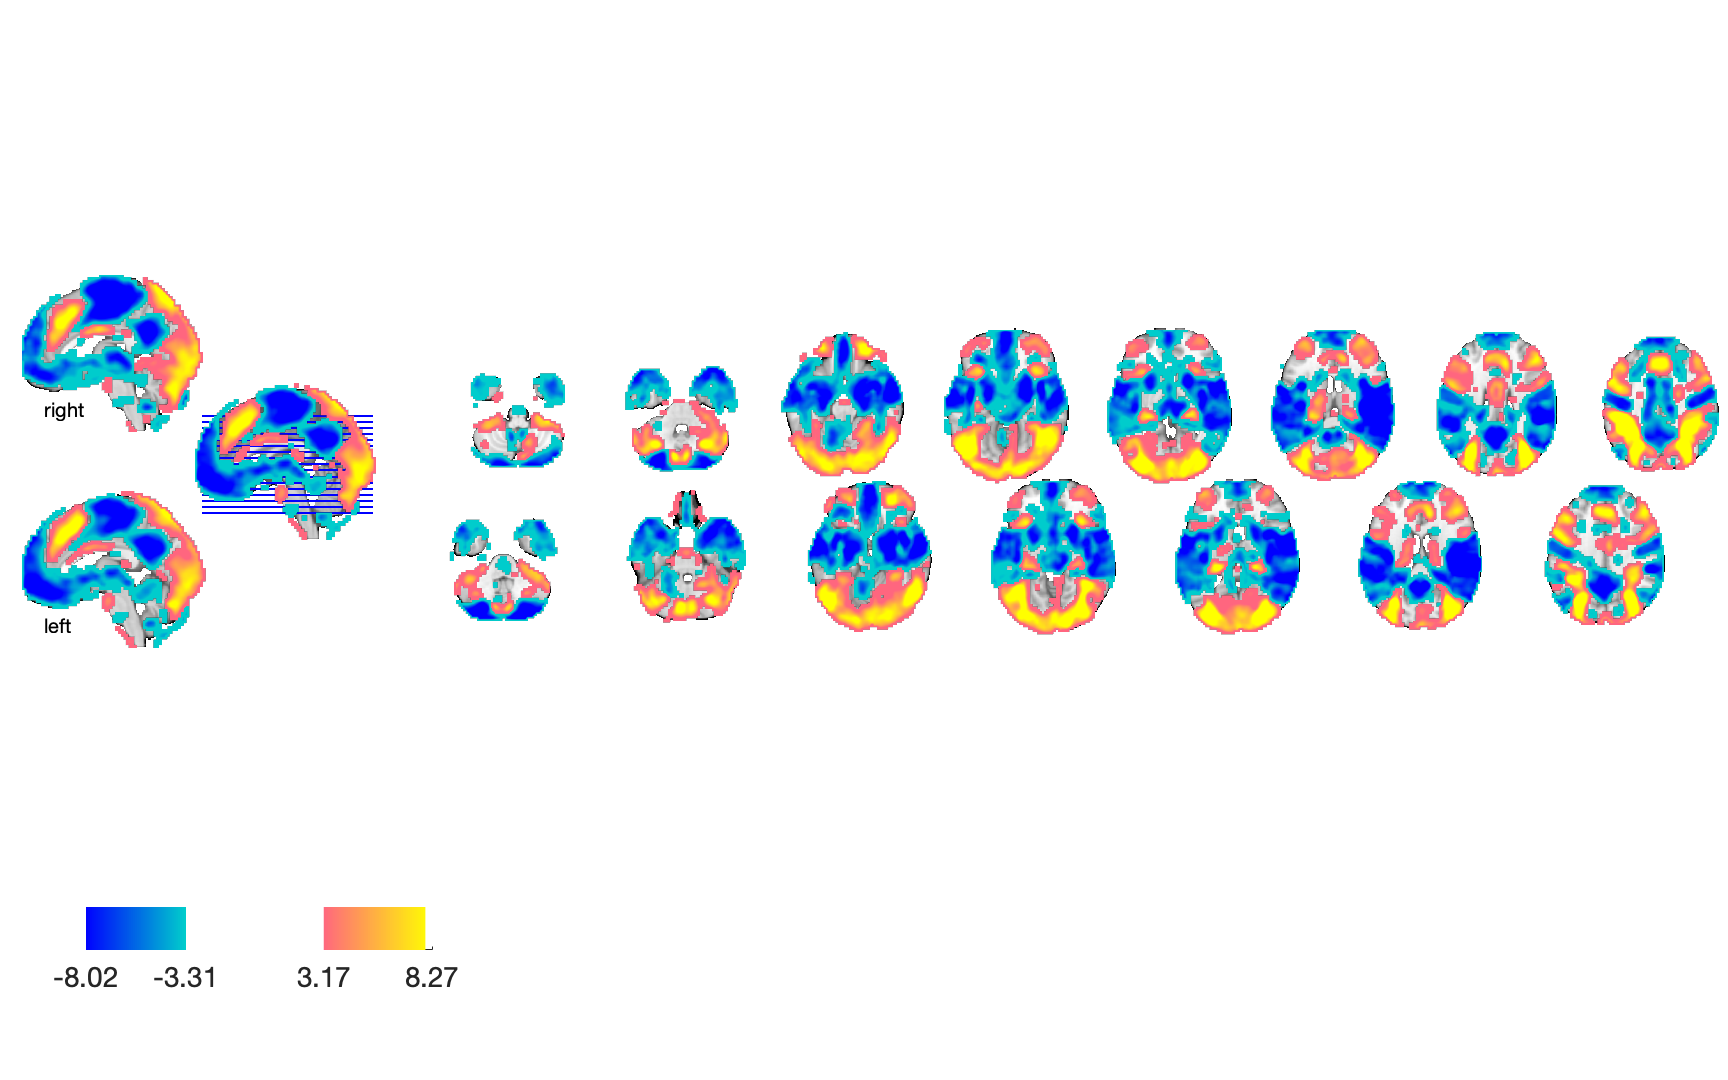

drawnow, snapnow;